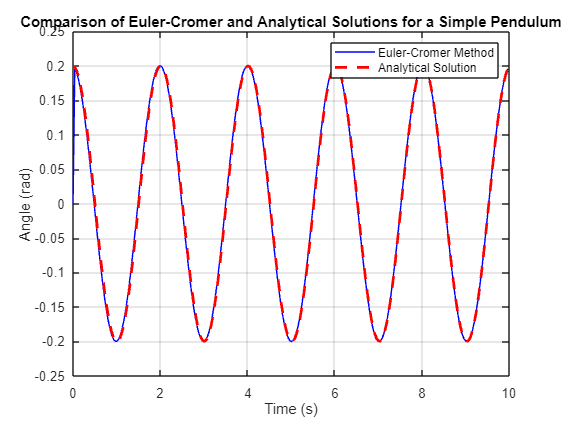

% Constants
g = 9.81;  % acceleration due to gravity (m/s^2)
length = 1; % length of the pendulum (m)
time_step = 0.04; % time step (s)
total_time = 10;  % total simulation time (s)
num_steps = total_time / time_step; % number of time steps

theta0 = 0.2; % initial angle (rad)
phi = 0; % phase constant

% Initial conditions
theta = theta0;  % initial angle (rad)
omega = 0.0;  % initial angular velocity (rad/s)

% Preallocate arrays for efficiency
theta_values = zeros(1, num_steps);
omega_values = zeros(1, num_steps);
time_values = 0:time_step:(total_time - time_step); % time array

time_values_analytical = 0:time_step:total_time; % time array for analytical

% Euler-Cromer Method Simulation
for i = 1:num_steps-1
    % Update angular velocity
    omega = omega - (g / length) * sin(theta) * time_step;
    % Update angle using new omega
    theta = theta + omega * time_step;
    
    % Store new values
    theta_values(i+1) = theta;
    omega_values(i+1) = omega;
end    

% The analytical solution
% Natural frequency of the pendulum
omega_natural = sqrt(g / length); 

% Analytical solution for theta as a function of time
theta_analytical = theta0 * cos(omega_natural * time_values_analytical + phi);

% Plotting
figure;
% Plot the Euler-Cromer Method
plot(time_values, theta_values, 'b-', 'DisplayName', 'Euler-Cromer Method');
hold on;
% Plot the Analytical Solution
plot(time_values_analytical, theta_analytical, 'r--','LineWidth',2, 'DisplayName', 'Analytical Solution');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Comparison of Euler-Cromer and Analytical Solutions for a Simple Pendulum');
legend show;
grid on;